## Problem 4

clc
clear
close all

q = 1.602e-19; % C
h = 6.626e-34; % Joule seconds
h_bar = h / (2*pi); % Joule seconds
KB_J = 1.381e-23; % Boltzmann constant in J/K
T = 300; % room temperature at degrees K
m_e = 9.109e-31; % electron rest mass in kg
m_gamma = 0.067 * m_e; % effective mass of electron in gamma valley
m_X = 0.58 * m_e; % effective mass of electron in X valley
m_L = 0.17 * m_e; % effective mass of electron in L valley
m_eff = [m_gamma m_X m_L];
E_phonon = 35.36e-3 * q; % energy of a phonon in GaAs in J
w_LO = E_phonon / h_bar; % rad/s for phonon in GaAs
e_s = 12.9; % static dielectric constant
e_inf = 10.9; % high-frequency dielectric constant
e_0 = 8.854e-12; % vacuum permittivity in F/m
N_0 = 1 / (exp(E_phonon / (KB_J * T)) - 1); % phonon occupation number
p = 5360; % mass density of GaAs, kg/m^3

**Initial Values**

E_kin = linspace(0, 2, 1000) * q;
Z_if = [0 3 4
        1 2 4
        1 3 3]; % # of final vallies
D_if = [0 10 1.8
        10 10 1
        1.8 1 5] * (q / 1e-10); % from eV / Angstrom to J/m
E_if = [0 .48 .29
       -.49 0 -.19
       -.29 .19 0] * q;
inter_phonon = [0 .0299 .0278
              .0299 .0299 .0293
              .0278 .0293 .029] * q; % intervalley phonon energy in eV
w_if = inter_phonon / h_bar;
D_acoustic = [7 9 9.2] * q; % Deformation potential in J for gamma, X, L valley
v_s = 5110; % sound velocity in GaAs in m/s

**a)**

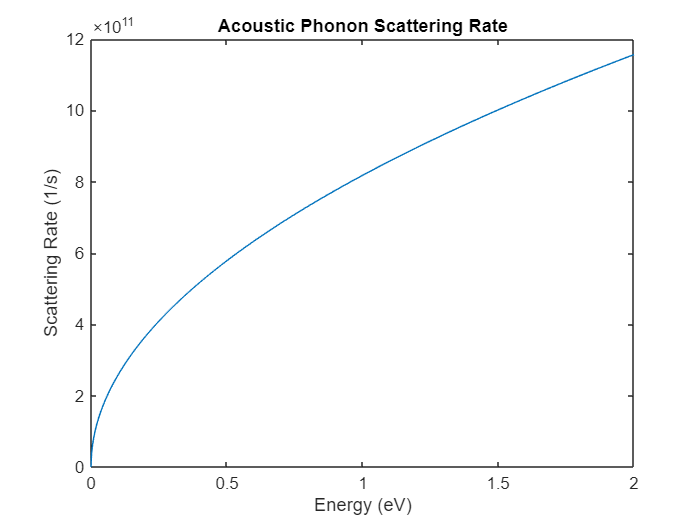

% Acoustic scattering
x = 1;
acoustic = ac_scatter(E_kin, m_eff(x), h_bar, p, v_s, D_acoustic(x), KB_J, T);
figure;
plot(E_kin / q, acoustic);
title('Acoustic Phonon Scattering Rate');
xlabel('Energy (eV)');
ylabel('Scattering Rate (1/s)');

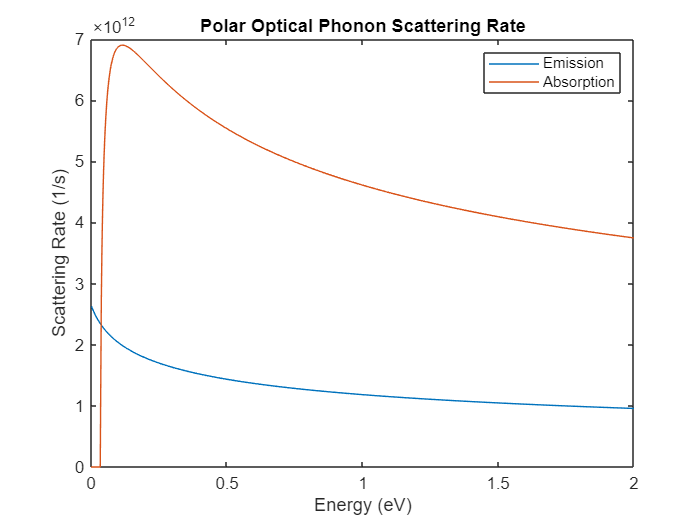


% Polar Optical (POP) scattering
figure;
emit_pop = pop_abs(E_kin, m_eff(x), h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T);
abs_pop = pop_emit(E_kin, m_eff(x), h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T);
plot(E_kin / q, emit_pop);
hold on;
plot(E_kin / q, abs_pop);
title('Polar Optical Phonon Scattering Rate');
xlabel('Energy (eV)');
ylabel('Scattering Rate (1/s)');
legend('Emission', 'Absorption');

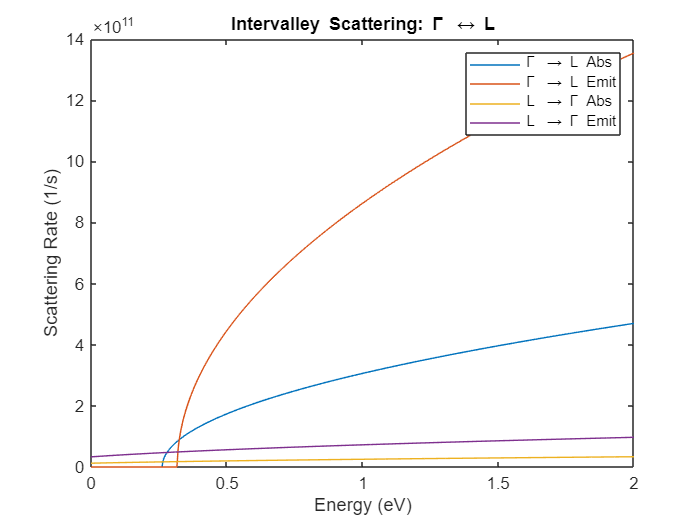


% Gamma <-> L
figure;
y = 3;
gamma_abs_L = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
gamma_emit_L = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(x, y), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
L_abs_gamma = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(y, x), Z_if(y, x), w_if(y, x), E_if(y, x), m_eff(x), p, inter_phonon(y, x));
L_emit_gamma = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(y, x), Z_if(y, x), w_if(y, x), E_if(y, x), m_eff(x), p, inter_phonon(y, x));
plot(E_kin / q, gamma_abs_L);
hold on;
plot(E_kin / q, gamma_emit_L);
plot(E_kin / q, L_abs_gamma);
plot(E_kin / q, L_emit_gamma);
title('Intervalley Scattering: \Gamma \leftrightarrow L');
xlabel('Energy (eV)');
ylabel('Scattering Rate (1/s)');
legend('\Gamma \rightarrow L Abs', '\Gamma \rightarrow L Emit', ...
       'L \rightarrow \Gamma Abs', 'L \rightarrow \Gamma Emit');

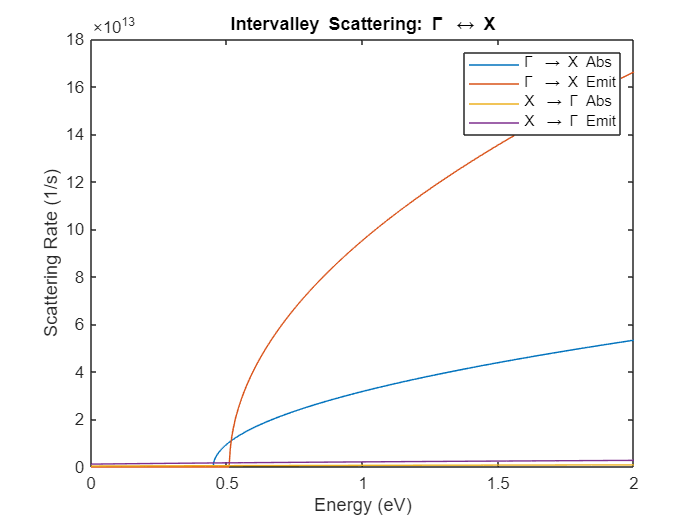


% Gamma <-> X
figure;
y = 2;
gamma_abs_X = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(y, x), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
gamma_emit_X = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(y, x), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
X_abs_gamma = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(y, x), Z_if(y, x), w_if(y, x), E_if(y, x), m_eff(x), p, inter_phonon(y, x));
X_emit_gamma = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(y, x), Z_if(y, x), w_if(y, x), E_if(y, x), m_eff(x), p, inter_phonon(y, x));
plot(E_kin / q, gamma_abs_X);
hold on;
plot(E_kin / q, gamma_emit_X);
plot(E_kin / q, X_abs_gamma);
plot(E_kin / q, X_emit_gamma);
title('Intervalley Scattering: \Gamma \leftrightarrow X');
xlabel('Energy (eV)');
ylabel('Scattering Rate (1/s)');
legend('\Gamma \rightarrow X Abs', '\Gamma \rightarrow X Emit', ...
       'X \rightarrow \Gamma Abs', 'X \rightarrow \Gamma Emit');

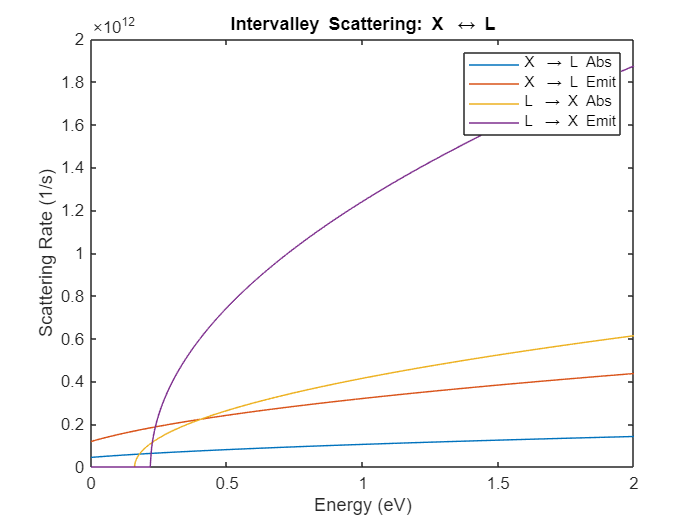


% X <-> L
figure;
x = 2; y = 3;
X_abs_L = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(y, x), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
X_emit_L = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(x, y), Z_if(x, y), w_if(y, x), E_if(x, y), m_eff(y), p, inter_phonon(x, y));
L_abs_X = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(y, x), Z_if(y, x), w_if(y, x), E_if(y, x), m_eff(x), p, inter_phonon(y, x));
L_emit_X = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(y, x), Z_if(y, x), w_if(y, x), E_if(y, x), m_eff(x), p, inter_phonon(y, x));
plot(E_kin / q, X_abs_L);
hold on;
plot(E_kin / q, X_emit_L);
plot(E_kin / q, L_abs_X);
plot(E_kin / q, L_emit_X);
title('Intervalley Scattering: X \leftrightarrow L');
xlabel('Energy (eV)');
ylabel('Scattering Rate (1/s)');
legend('X \rightarrow L Abs', 'X \rightarrow L Emit', ...
       'L \rightarrow X Abs', 'L \rightarrow X Emit');

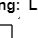


% X <-> X and L <-> L
figure;
y = 3;
L_abs_L = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(y, y), Z_if(y, y), w_if(y, y), E_if(y, y), m_eff(y), p, inter_phonon(y, y));
L_emit_L = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(y, y), Z_if(y, y), w_if(y, y), E_if(y, y), m_eff(y), p, inter_phonon(y, y));
y = 2;
X_abs_X = inter_scatter_abs(E_kin, h_bar, KB_J, T, D_if(y, y), Z_if(y, y), w_if(y, y), E_if(y, y), m_eff(y), p, inter_phonon(y, y));
X_emit_X = inter_scatter_emit(E_kin, h_bar, KB_J, T, D_if(y, y), Z_if(y, y), w_if(y, y), E_if(y, y), m_eff(y), p, inter_phonon(y, y));
plot(E_kin / q, L_abs_L);
hold on;
plot(E_kin / q, L_emit_L);
plot(E_kin / q, X_abs_X);
plot(E_kin / q, X_emit_X);
title('Intravalley Scattering: L \leftrightarrow L and X \leftrightarrow X');
xlabel('Energy (eV)');
ylabel('Scattering Rate (1/s)');
legend('L \rightarrow L Abs', 'L \rightarrow L Emit', ...
       'X \rightarrow X Abs', 'X \rightarrow X Emit');

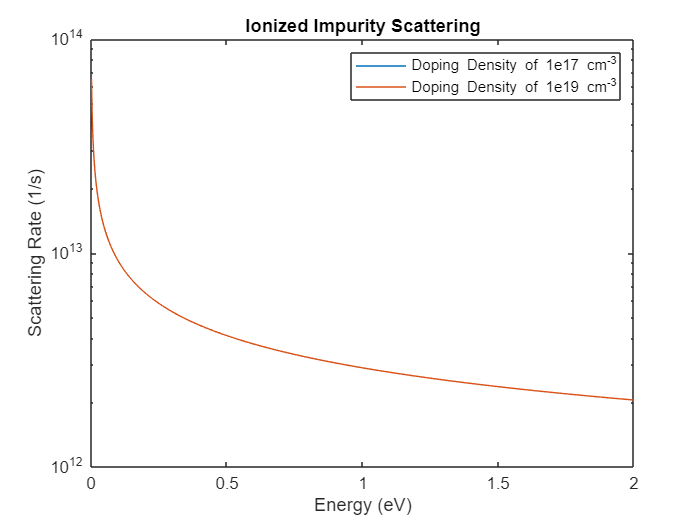


figure;
x = 1;
ion_imp_less_doped = ion_imp(E_kin, 1e17, 1, q, h_bar, e_0, e_s, m_eff(x), T, KB_J);
ion_imp_more_doped = ion_imp(E_kin, 1e19, 1, q, h_bar, e_0, e_s, m_eff(x), T, KB_J);
semilogy(E_kin / q, ion_imp_less_doped);
hold on;
semilogy(E_kin / q, ion_imp_more_doped);
title('Ionized Impurity Scattering');
xlabel('Energy (eV)');
ylabel('Scattering Rate (1/s)');
legend('Doping Density of 1e17 cm^{-3}', 'Doping Density of 1e19 cm^{-3}');

**b)**

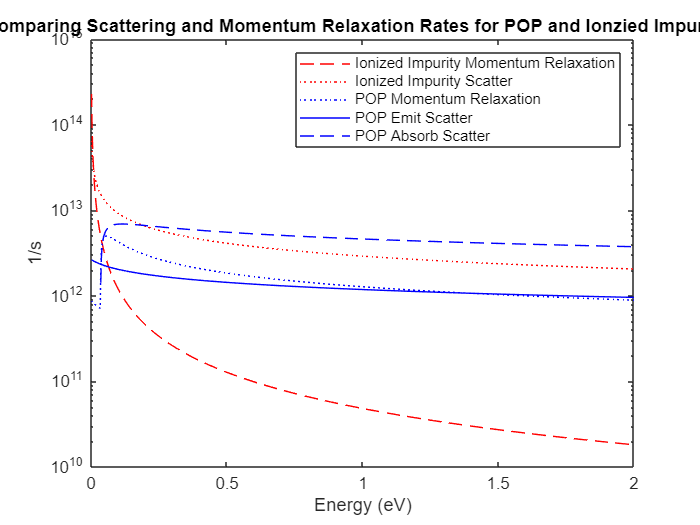

x = 1;
% Momentum Rates
ionized_momentum = ionized_k(E_kin, 1e19, 1, q, h_bar, e_0, e_s, m_eff(x), T, KB_J);
figure;
semilogy(E_kin/ q, ionized_momentum, 'r--');
hold on;
semilogy(E_kin / q, ion_imp_more_doped, 'r:');

% Scatter Rates
emit_pop_scatter = pop_abs(E_kin, m_eff(x), h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T);
abs_pop_scatter = pop_emit(E_kin, m_eff(x), h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T);
pop_k = pop_momentum(E_kin, E_phonon, m_eff(x), h_bar, KB_J, T, q, e_inf, e_s, e_0, w_LO);
semilogy(E_kin / q, pop_k, 'b:');
semilogy(E_kin / q, emit_pop_scatter, 'b-');
semilogy(E_kin / q, abs_pop_scatter, 'b--');
legend('Ionized Impurity Momentum Relaxation', 'Ionized Impurity Scatter', ...
    'POP Momentum Relaxation', 'POP Emit Scatter', 'POP Absorb Scatter');
title('Comparing Scattering and Momentum Relaxation Rates for POP and Ionzied Impurities');
ylabel('1/s');
xlabel('Energy (eV)');

**Ionized Impurity Momentum Relaxation**

function ion_relax = ionized_k(E, n, Z, q, h_bar, e_0, e_s, m, T, KB_J)
    e_0 = e_0 / 100; % converting to F/cm to match cm^-3 concentration
    k = sqrt(2 * m * E / h_bar^2);
    ion_relax = zeros(1, length(k));
    Ld = sqrt((e_0 * e_s * T * KB_J) / (n * q ^ 2));

    X = (n * Z^2 * q^4 * m) / (8 * pi * h_bar^3 * e_0^2 * e_s^2);

    for j = 1:length(k)
        B = 4 * k(j)^2 * Ld^2;
        ion_relax(j) = (X / k(j)^3) * (log(1 + B) - (B / (1 + B)));
    end
end

**POP Relaxation**

function pop_k = pop_momentum(E_kin, E_phonon, m, h_bar, KB_J, T, q, e_inf, e_s, e_0, w_LO)
    k = sqrt(2 * m * E_kin / h_bar^2);
    k_ph = sqrt(2 * m * E_phonon / h_bar^2);
    N0 = 1 / (exp(E_phonon / (KB_J * T)) - 1);
    pop_k = zeros(1, length(E_kin));
    absorb = pop_k; emit = pop_k;
    
    for j = 1:length(E_kin)
        X = (q^2 * w_LO * (e_s / e_inf - 1)) / (4 * pi * e_s * e_0 * h_bar * sqrt(2 * E_kin(j) / m));

        absorb(j) = X * (N0 * sqrt(1 + E_phonon / E_kin(j)) - ...
            (E_phonon * N0 / E_kin(j)) * asinh(sqrt(E_kin(j) / E_phonon)));
        if E_kin(j) > E_phonon
            emit(j) = X * ((N0 + 1) * sqrt(1 - E_phonon / E_kin(j)) + ...
                (E_phonon * (N0 + 1) / E_kin(j)) * asinh(sqrt(E_kin(j) / E_phonon - 1)));
        else
            emit(j) = 0;
        end
    end
    pop_k = absorb + emit;
end

**Polar-Optical-Phonon Scattering**

function pop_scatter = pop_emit(E, m, h_bar, w_0, E_phonon, KB_J, q, e_inf, e_s, e_0, T)
    pop_scatter = zeros(1, length(E));
    for i = 1:length(E)
        x = h_bar * w_0 / E(i);
        C = ((q^2 * w_0) / (8 * pi * e_0)) * sqrt(2 * m / (h_bar^2)) * ...
            ((1 / e_inf) - (1 / e_s)) * (1 / sqrt(E(i)));
        N_0 = 1 / (exp(E_phonon / (KB_J * T)) - 1);
    
        if E(i) > (h_bar * w_0)
            pop_scatter(i) = C * ((N_0 + 1) * log(abs((1 + sqrt(1 - x)) / (1 - sqrt(1 - x)))));
        end
    end
end

function pop_scatter = pop_abs(E, m, h_bar, w_0, E_phonon, KB_J, q, e_inf, e_s, e_0, T)
    pop_scatter = zeros(1, length(E));
    for i = 1:length(E)
        x = h_bar * w_0 / E(i);
        C = ((q^2 * w_0) / (8 * pi * e_0)) * sqrt(2 * m / (h_bar^2)) * ...
            ((1 / e_inf) - (1 / e_s)) * (1 / sqrt(E(i)));
        N_0 = 1 / (exp(E_phonon / (KB_J * T)) - 1);
    
        pop_scatter(i) = C * (N_0 * log(abs((1 + sqrt(1 + x)) / (-1 + sqrt(1 + x)))));
    end
end

**Acoustic**

function acoustic = ac_scatter(E, m, h_bar, p, v_s, D, KB_J, T)
    acoustic = (D^2 * KB_J * T) / (2 * pi * h_bar * p * v_s^2) * ...
        ((2 * m) / (h_bar ^ 2)) ^ 1.5 * sqrt(E);
end

**Intervalley Scattering**

function gamma_inter_abs = inter_scatter_abs(E, h_bar, KB_J, T, D_if, Z_if, w_if, E_if, m_final, p, E_phonon)
    gamma_inter_abs = zeros(1, length(E));
    for j = 1:length(E)
        N_if = 1 / (exp(h_bar * w_if / (KB_J * T)) - 1);
        g_DOS = DOS(E(j) + E_phonon - E_if, m_final, h_bar);
        gamma_inter_abs(j) = N_if * (pi * D_if^2 * Z_if / (2 * p * w_if)) * g_DOS;
    end
end

function gamma_inter_emit = inter_scatter_emit(E, h_bar, KB_J, T, D_if, Z_if, w_if, E_if, m_final, p, E_phonon)
    gamma_inter_emit = zeros(1, length(E));
    for j = 1:length(E)
        N_if = 1 / (exp(h_bar * w_if / (KB_J * T)) - 1);
        g_DOS = DOS(E(j) - E_phonon - E_if, m_final, h_bar);
        gamma_inter_emit(j) = (N_if + 1) * (pi * D_if^2 * Z_if / (2 * p * w_if)) * g_DOS;
    end
end

**Ionized Impurities**

function ion_impurities = ion_imp(E, n, Z, q, h_bar, e_0, e_s, m, T, KB_J)
    k = sqrt(2 * m * E / h_bar^2);
    ion_impurities = zeros(1, length(k));
    Ld = sqrt((e_0 * e_s * T * KB_J) / (n * q ^ 2));

    X = (n * Z^2 * q^4 * Ld^4 * m) / (pi * h_bar^3 * e_0^2 * e_s^2);

    for j = 1:length(k)
        ion_impurities(j) = X * (k(j) ./ (4 * k(j)^2 * Ld^2 + 1));
    end
end

**DOS**

function g_DOS = DOS(E, m, h_bar)
    if E > 0
        g_DOS = (sqrt(E) / (2 * (pi^2))) * (2 * m / (h_bar ^ 2)) ^ 1.5;
    else
        g_DOS = 0;
    end
end